## **Homework #3 BME 526: Intro to Neural Engineering (Spring 2024)**

## **Anirudh Iyengar Kaniyar Narayana Iyengar**

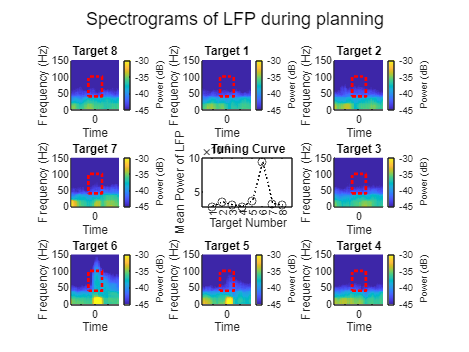

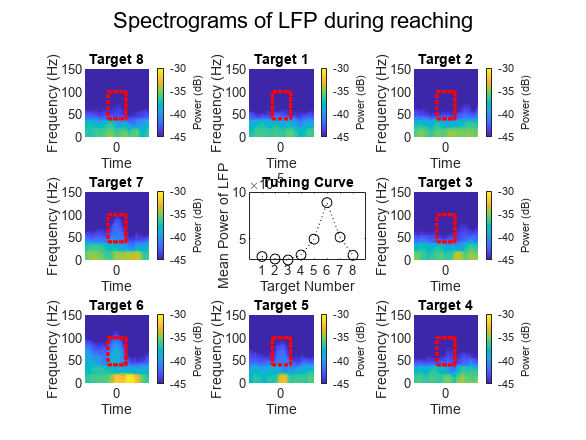

clc; clear;

load("LIPdata.mat")

params.tapers = [5 9];
params.pad = 2;
params.Fs = 1000; % Sampling rate
params.fpass = [0 150]; % Selecting the Spectrograms frequency range 0-150Hz
params.trialave = 1;
params.err = 0;
movingwin = [0.250 0.025]; % duration of moving window used to evaluate spectrograms
w = [1.0 2.2]; % window around events i.e., planning and reaching of saccades in LIP
figureplacer = [2 3 6 9 8 7 4 1]; % Matching the target placement with the one in the
timebounds = [-0.25 0.25 0.25 -0.25 -0.25]; % For drawing the red visual window
freqbounds = [40 40 100 100 40]; % For drawing the red visual window
Power_Avg = zeros; % Makes the code faster

%% Looping through the event windows to get two outputs
tic; % Timing the code ~ 3 seconds
for e = 1:2
    figure; % Eight targets with a tuning curve in the middle
    for t = 1:8
        E = targoff(find(targets == t - 1));
        [Slfp, tlfp, flfp] = mtspecgramtrigc(dlfp(:, 1), E, w, movingwin, params);
        tlfp = tlfp - w(e); % Aligning the Spectrogram to the event window
        subplot(3, 3, figureplacer(t));
        hold on;
        imagesc(tlfp, flfp, 10 * log10(Slfp)');
        plot(timebounds, freqbounds, ':r', 'LineWidth', 2); % Window just for visual
        axis xy;
        a = colorbar;
        a.Label.String = 'Power (dB)';
        caxis([-45 -30]); % Plot all spectrograms with the same power range
        ylim([0 150]);
        xlim([-0.8865 0.8885]);
        xlabel('Time');
        ylabel('Frequency (Hz)');
        t1 = 'Target 1';
        t2 = 'Target 2';
        t3 = 'Target 3';
        t4 = 'Target 4';
        t5 = 'Target 5';
        t6 = 'Target 6';
        t7 = 'Target 7';
        t8 = 'Target 8';
        E = {t1, t2, t3, t4, t5, t6, t7, t8};
        title(E{t});
        % Setting Time bounds to select the duration of LFP (~0.5s)
        timebounds_min = find(tlfp >= -0.25, 1, 'first');
        timebounds_max = find(tlfp <= 0.25, 1, 'last');
        % Setting Frequency bounds to select LFP (<100Hz)
        freqbounds_min = find(flfp >= 40, 1, 'first');
        freqbounds_max = find(flfp <= 100, 1, 'last');
        % The Window with time and frequency bounds to take power averages
        Window = Slfp(timebounds_min:timebounds_max, freqbounds_min:freqbounds_max);
        Power_Avg(t) = mean(mean(Window));
    end
    % Tuning Curve of all targets
    subplot(3, 3, 5)
    plot(Power_Avg, ':ok', 'MarkerEdgeColor', 'k');
    xlim([0, 9]);
    xticks([1 2 3 4 5 6 7 8]);
    xticklabels({'1', '2', '3', '4', '5', '6', '7', '8'});
    xlabel('Target Number');
    ylabel('Mean Power of LFP');
    title('Tuning Curve');
    if e == 1
        sgtitle('Spectrograms of LFP during planning');
    end
    if e == 2
        sgtitle('Spectrograms of LFP during reaching');
    end
end

toc; % Timing the code

Elapsed time is 8.794874 seconds.


**Frequency limits are established due to local field potentials occurring between 40Hz and 100Hz, lasting approximately half a second (i.e., the time constraints). Time boundaries are set from -0.25 to 0.25, aligned with zero. The analysis window spans roughly 1 second for planning, while the saccade's reaching duration is approximately 2.2 seconds. These parameters are configured in the spectrogram to assess power averages for inputting into the tuning curve.**